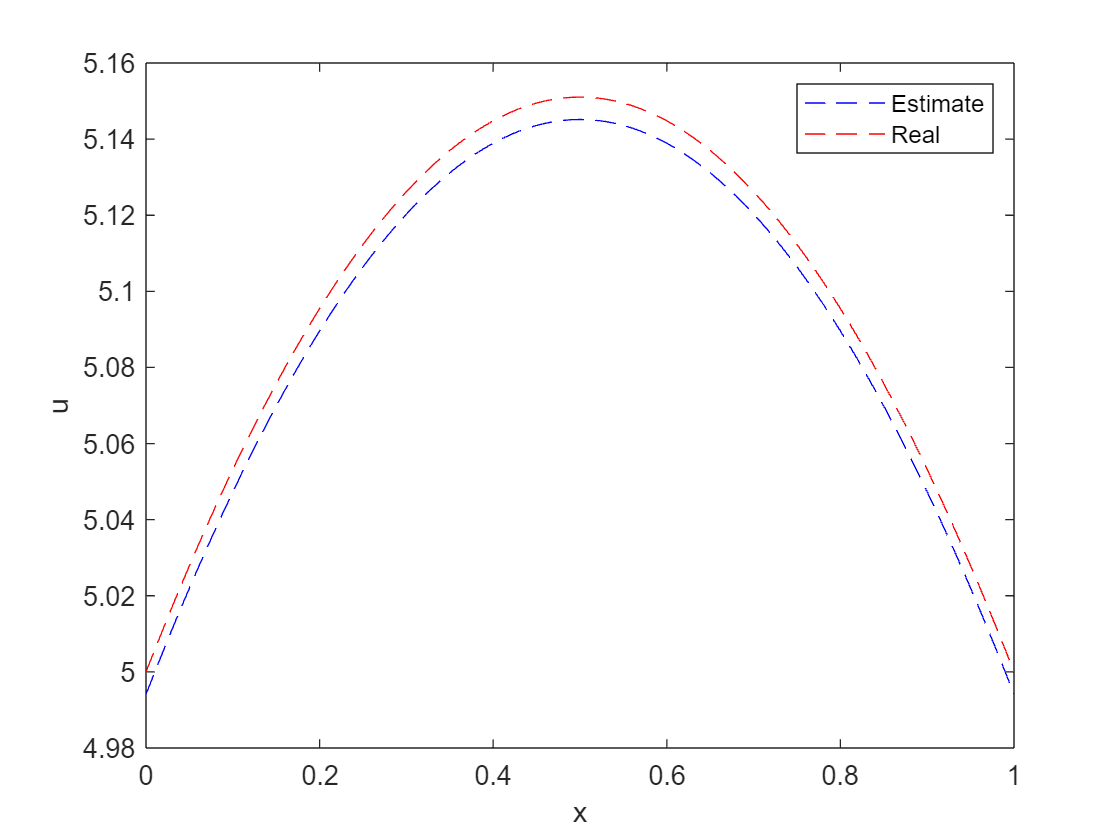

% N
n_1=100;


% Interval
h_1=1/n_1;


% X-axis
x_1=0:h_1:1;



% Initialize stiffness matrix, vector 
K_1=zeros(n_1+1,n_1+1);

f_1=zeros(n_1+1,1);



% Compute vector
syms x;
exp1=-x^2+x+1;
for i=1:n_1+1
    if i==1
        exp2=1-n_1*x;
        f_1(i,1)=int(exp2*exp1,x,0,1/n_1*i);
    elseif i==n_1+1
        exp2=n_1*x-(n_1-1);
        f_1(i,1)=int(exp2*exp1,x,1-1/n_1,1);
    else
        exp2=n_1*x-(i-2);
        exp3=-n_1*x+i;
        f_1(i,1)=int(exp2*exp1,x,1/n_1*(i-2),1/n_1*(i-1))+int(exp3*exp1,x,1/n_1*(i-1),1/n_1*i);
    end
end
% Compute stiffness matrix

for i=1:n_1+1
    for j=1:n_1+1
        % overlapping condition 1
        if i==j
            if i==1
                K_1(i,j)=n_1-100;
            elseif i==n_1+1
                K_1(i,j)=n_1-100;
            else
                K_1(i,j)=n_1*2;
            end
        % overlapping condition 2
        elseif j-i==1
            if i==1
                K_1(i,j)=-n_1+50;
            else
                K_1(i,j)=-n_1;
            end
        elseif i-j==1
            if i==n_1+1
                K_1(i,j)=-n_1+50;
            else
                K_1(i,j)=-n_1;
            end
        end
    end
end



% Solution
U_1=K_1\f_1;


y_1=zeros(n_1+1,1);
for i=1:n_1+1
    y_1(i,1)=U_1(i,1)+5;
end

y_2=zeros(n_1+1,1);
for i=1:n_1+1
    y_2(i,1)=1/12*x_1(1,i)^4-1/6*x_1(1,i)^3-1/2*x_1(1,i)^2+7/12*x_1(1,i)+5;
end

y_3=zeros(n_1+1,1);
for i=1:n_1+1
    y_3(i,1)=-x_1(1,i)^2+x_1(1,i)+1;
end

y_4=zeros(n_1/10,1);
for i=1:n_1/10
    y_4(i,1)=y_2(i*10+1,1)-y_1(i*10+1,1);
end

x=zeros(n_1+1,1);
for i=1:n_1+1
    x(i,1)=x_1(1,i);
end

x_2=zeros(n_1/10,1);
for i=1:n_1/10
    x_2(i,1)=x_1(1,i*10+1);
end
% Temperature
figure;
plot( x_1, y_1, 'b--',x_1,y_2,'r--');
xlabel('x'); ylabel('u');
legend('Estimate','Real');

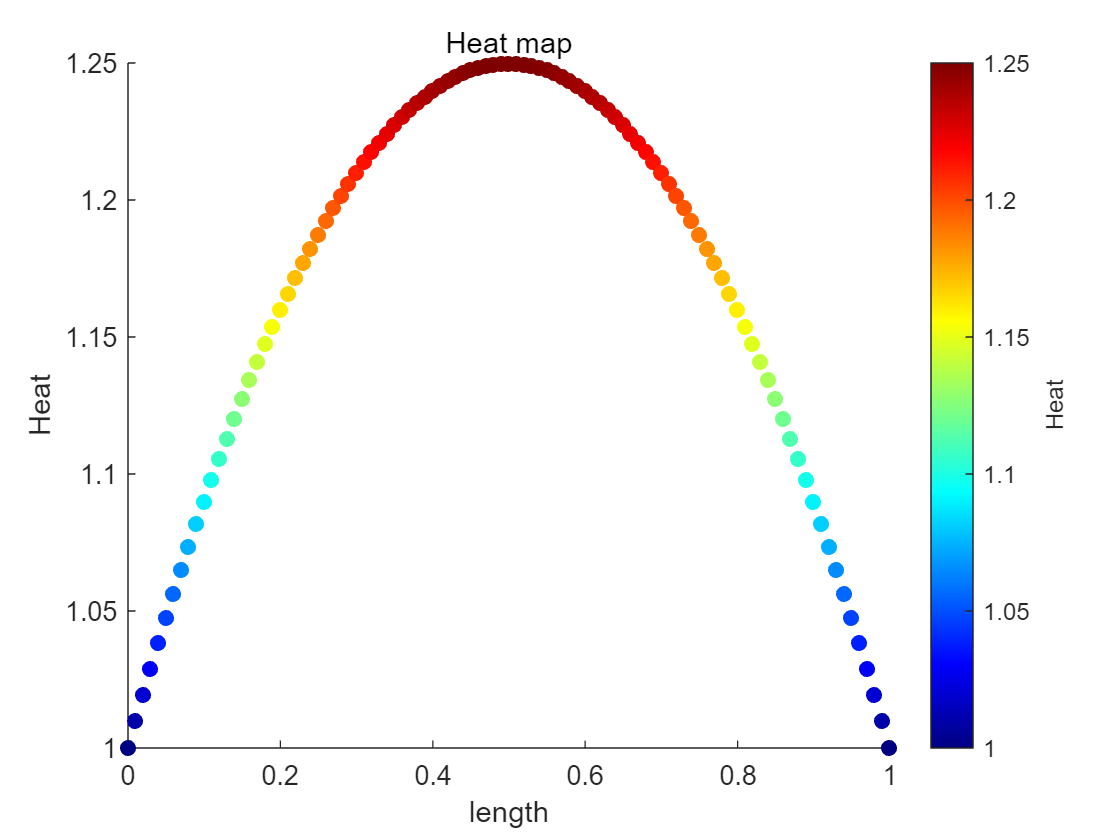


% Heat
figure;
scatter(x, y_3, 36, y_3, 'filled');

colorbar;
colormap(jet); 

xlabel('length');
ylabel('Heat');
title('Heat map');

c = colorbar;
c.Label.String = 'Heat';